# Sp2n型量子群の表現を構築するための代数構造の多項式表示

## 動機

C_n型量子群のmodule algebraは非可換変数としては既に得られている。これを可換変数で表示したい。

そのために可換変数で積構造の微分演算子による表示を解析する。

C_2型は既に達成されているので、一般化を試みる。

quantum symplectic spaceの定義をする。

## Uq(sp_2n)-modalgの定義

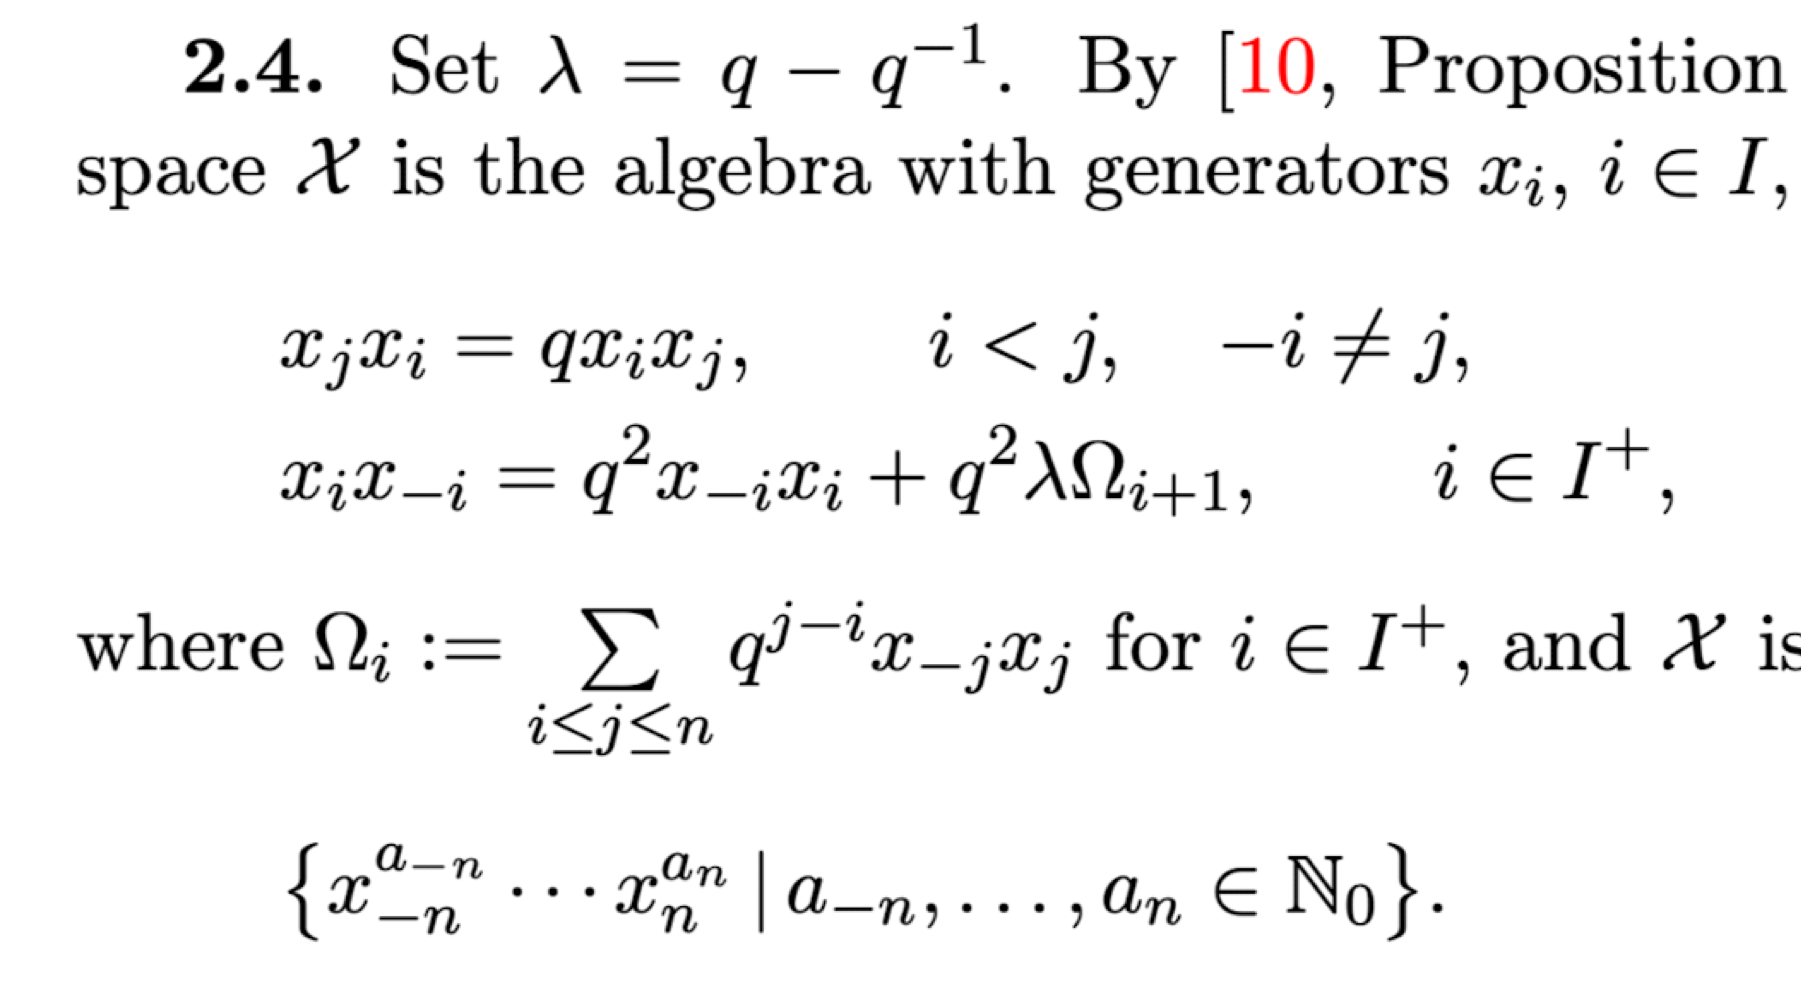

syms q
set(CR.H,di=1)
s=@simplify;

## Uqsp4modalgクラスによる規則性の発見

### strAlgによる計算

ll=3;
% [O,Xm2,Xm1,X1,X2]=strCnmodalg2.getGenerator(ll,"all");
[O,Y]=strCnmodalg2.getGenerator(ll,"dict");

計算の確認

Xm1*X2*Xm1*X1

関数または変数 'Xm1' が認識されません。

X1^2*Xm1^2
X1^2*Xm1^5

a=2;
am1=1;
A1=X(1)^a*X(-1)^am1*q^{-2*a*am1}

A1 =         coeff            base    
    _____________    ____________
    (q^4 - 1)/q      x_m3 x_1 x_3
    (q^4 - 1)/q^2    x_m2 x_1 x_2
    1                x_m1 x_1 x_1

A1.cf=s(A1.cf./cellfun(@(pw)gtN(pw,am1,a),A1.pw))

A1 =             coeff                base    
    _____________________    ____________
    (q^4 + q^2)/(q^2 - 1)    x_m3 x_1 x_3
    (q^3 + q)/(q^2 - 1)      x_m2 x_1 x_2
    q^3/(q^2 - 1)^2          x_m1 x_1 x_1

function ret=gtN(pw,am1,a1)
    qN=qNumS;
    q=qN.q;
    l=length(pw)/2;
    N=a1-sum(pw==l+1);
    ret=qN.T^(N)*q^(-N*(N-1)/2)*qN.fac(a1)*qN.fac(am1)/qN.fac(a1-N)/qN.fac(am1-N)/qN.fac(N);
end

A1=X(1)^2*X(-1)^2

A1 =               coeff                    base       
    _________________________    _________________
    q^6*(q^2 - 1)^2*(q^2 + 1)    x_m3 x_m3 x_3 x_3
    q^5*(q^4 - 1)^2              x_m3 x_m2 x_2 x_3
    q^6*(q^2 - 1)*(q^2 + 1)^2    x_m3 x_m1 x_1 x_3
    q^4*(q^2 - 1)^2*(q^2 + 1)    x_m2 x_m2 x_2 x_2
    q^5*(q^2 - 1)*(q^2 + 1)^2    x_m2 x_m1 x_1 x_2
    q^8                          x_m1 x_m1 x_1 x_1

for ii=2:4
    B1=X(1)^2*X(-1)^ii;
    disp(s(B1.cf./A1.cf).')
end

$$\left(\begin{array}{cccccc} 1 & 1 & 1 & 1 & 1 & 1 \end{array}\right)$$

$$\left(\begin{array}{cccccc} q^{6}+q^{4}+q^{2} & q^{6}+q^{4}+q^{2} & \frac{q^{7}+q^{5}+q^{3}}{q^{2}+1} & q^{6}+q^{4}+q^{2} & \frac{q^{7}+q^{5}+q^{3}}{q^{2}+1} & q^{4} \end{array}\right)$$

$$\left(\begin{array}{cccccc} q^{12}+q^{10}+2\,q^{8}+q^{6}+q^{4} & q^{4}\,\left(q^{8}+q^{6}+2\,q^{4}+q^{2}+1\right) & q^{10}+q^{6} & q^{12}+q^{10}+2\,q^{8}+q^{6}+q^{4} & q^{10}+q^{6} & q^{8} \end{array}\right)$$

乗算表

multipleTbl(X,'a=X(i);b=prodeval(X(-j)|X(-k));')

Incorrect number or types of inputs or outputs for function disp2.
エラー: Calc241228Cnmodalg>multipleTbl (行 42)
    disp2(str)

multipleTbl(X,'a=X(i);b=prodeval(X(-j)|X(k));')


function multipleTbl(X,code)
    l=length(X.keys)/2;
    str=strings(1+l,1+l^2);
    for i=1:l
        for j=1:l
            for k=1:l
                eval(code)
                str(1+i,1+j+l*(k-1))=latex(a*b);
                str(1+i,1)=latex(a);
                str(1,1+j+l*(k-1))=latex(b);
            end
        end
    end
    disp2(str)
end

a=2;
am1=4;
b=-2;
c=1;
commeval(X(-1)^am1|X(b)^c)
if false
    A1=X(1)^a;
    A2=commeval(X(-1)^am1|X(b)^c);
    A1=A1*A2*q^{-2*a*am1};
    B1=X(1)^a*X(-1)^am1*q^{-2*a*am1};
else
    A1=commeval(X(1)^a|X(b)^c);
    A2=X(-1)^am1;
    A1=A1*A2*q^{-2*a*am1};
    B1=X(1)^a*X(-1)^am1*q^{-2*a*am1};
end
fprintf("(%s)*(%s)",latex(A1),latex(A2));disp1(A1)
disp(simplify(A1.cf./B1.cf).')

a=2;
am1=5;
b=-3;
c=1;
commeval(X(-1)^am1|X(b)^c)
A1=X(2)^a*commeval(X(-2)^am1|X(b)^c)*q^{-2*a*am1};
disp1(A1)

### sympによる計算 symCnalg

ll=3;
syms q
qN=qNumS(q);
s=@simplify;
v=symCnmodalg.getGenerator(ll);

v(1)^2*v(-1)^2
v(1)*v(-1)
v(1)^2.*v(-1)^5

clear a b
% Initialize a1 and b1 with 6 elements
a(1) = 4;
a(2) = 2;
a(3) = 4;
a(4) = 4;
a(5) = 2;
a(6) = 2;
b(1) = 3;
b(2) = 2;
b(3) = 2;
b(4) = 1;
b(5) = 2;
b(6) = 5;
% Update the expressions to use v(-3) to v(3)
A1=v(-3)^a(1) .* v(-2)^a(2) .* v(-1)^a(3) .* v(1)^a(4) .* v(2)^a(5) .* v(3)^a(6);
A2=v(-3)^b(1) .* v(-2)^b(2) .* v(-1)^b(3) .* v(1)^b(4) .* v(2)^b(5) .* v(3)^b(6);

B1=X(-3)^a(1) .* X(-2)^a(2) .* X(-1)^a(3) .* X(1)^a(4) .* X(2)^a(5) .* X(3)^a(6);
B2=X(-3)^b(1) .* X(-2)^b(2) .* X(-1)^b(3) .* X(1)^b(4) .* X(2)^b(5) .* X(3)^b(6);

disp(A1)

    coeff    x_m3    x_m2    x_m1    x_1    x_2    x_3
    _____    ____    ____    ____    ___    ___    ___
      1       4       2       4       4      2      2 


disp(A2)

    coeff    x_m3    x_m2    x_m1    x_1    x_2    x_3
    _____    ____    ____    ____    ___    ___    ___
      1       3       2       2       1      2      5 


A3=A1*A2+0+0+0
B3=B1*B2+0+0+0+0
simplify(flip(A3.cf)./B3.cf).'

## strC4modalgでパラメータを決定する

経験的に、$x_1*(x_bx_{-1})
$の計算と規則性からパラメータを完全に決定できる。

ll=4;
[O,X]=strCnmodalg2.getGenerator(ll);

b = -2;
A=X(1)*(X(b).*X(-1))

A =       coeff          base     
    _________    _____________
    q^7 - q^5    x_m4 x_m2 x_4
    q^6 - q^4    x_m3 x_m2 x_3
    q^4 - q^2    x_m2 x_m2 x_2
    q^3          x_m2 x_m1 x_1

B=X(1)*X(-1)

B =       coeff        base  
    _________    ________
    q^5 - q^3    x_m4 x_4
    q^4 - q^2    x_m3 x_3
    q^3 - q      x_m2 x_2
    q^2          x_m1 x_1

simplify(A.cf./B.cf).'

$$ans = \left(\begin{array}{cccc} q^{2} & q^{2} & q & q \end{array}\right)$$

## 結合律の検証


M1=repmat(v(1)*0,2*ll,2*ll,2*ll);

Mat =      0     0     0     0     0     0
     1     0     0     0     0     0
     1     1     0     0     0     0
     1     1     2     0     0     0
     1     2     1     1     0     0
     2     1     1     1     1     0


set relations


M2=repmat(v(1)*0,2*ll,2*ll,2*ll);
index=[-ll:-1 1:ll];
for ii=1:2*ll
    for jj=1:2*ll
        for kk=1:2*ll
            % (**)*
            M1(ii,jj,kk)=(v(index(ii))*v(index(jj)))*v(index(kk));
            % *(**)
            M2(ii,jj,kk)=v(index(ii))*(v(index(jj))*v(index(kk)));
        end
    end
end

次を使用中のエラー:  () 
キーが見つかりません。

O=v(1)-v(1);
Md=arrayfun(@minus,M1,M2);
Md0=arrayfun(@isequal,Md,repmat(O,2*ll,2*ll,2*ll))

Md0 = 8×8×8 の logical 配列
Md0(:,:,1) =
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
Md0(:,:,2) =
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
Md0(:,:,3) =
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
Md0(:,:,4) =
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1

生成元に対する結合律は成立している。

## strCnmodalgを導入

一般のnに対して定義できるように拡張した。n=2で検証


[O,Xm2,Xm1,X1,X2]=strCnmodalg2.getGenerator(2)
X1^2*Xm1^5

ll=3;
eval(sprintf("[O,%s]=strCnmodalg2.getGenerator(%d);",join(["Xm"+(ll:-1:1) "X"+(1:ll)],","),ll));

X1^2*Xm1^2+0